% Generate p1
p1 = [[0 0];[0 -1];[0 -2];[0 -3]]

p1 =      0     0
     0    -1
     0    -2
     0    -3


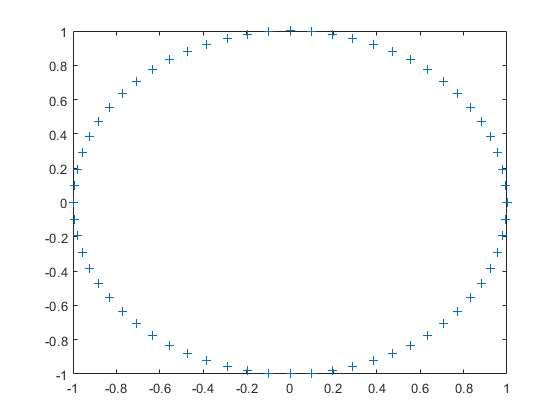

p2 =     0.9952    0.0980
    0.9808    0.1951
    0.9569    0.2903
    0.9239    0.3827
    0.8819    0.4714
    0.8315    0.5556
    0.7730    0.6344
    0.7071    0.7071
    0.6344    0.7730
    0.5556    0.8315


%Generate p2 using circle function at the bottom of the file
p2=circle(0,0,1)

%Generate p3 and p4. 
p3=butterfly(4,4);
p4=butterfly(2,2);

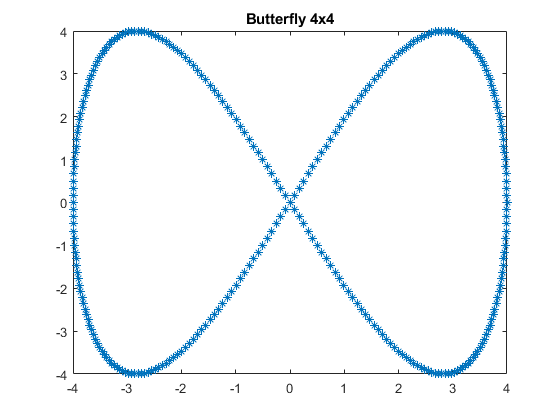

plot(p3(:,1), p3(:,2), '*')
title('Butterfly 4x4');

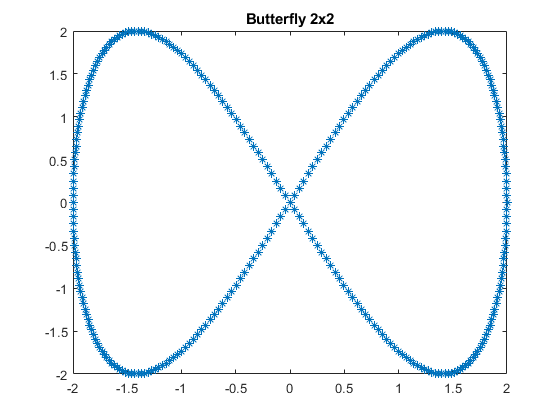

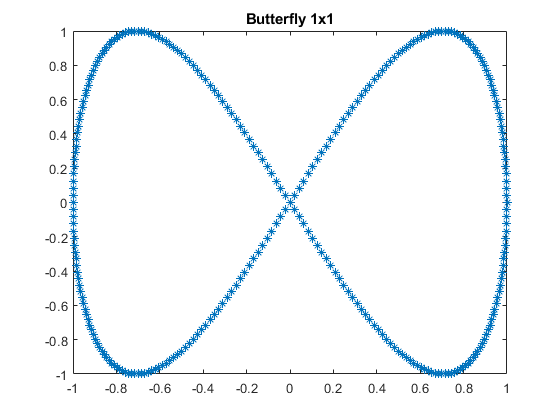

plot(p4(:,1), p4(:,2), '*')
title('Butterfly 2x2');

function p=circle(x,y,r)
%create and plot a circle with radius r and origin (x,y)
    ang=(2*pi/64):(2*pi/64):2*pi; 
    xp=r*cos(ang);
    yp=r*sin(ang);
    plot(x+xp,y+yp,"+");
    p=[xp;yp]';
end

function p=butterfly(width, height)
    freq = 2*pi/30;
    Ts = 0.1; % Sampling time
    t = 0:Ts:30; % Simulation time
    xRef = 0 + width*sin(freq*t);
    yRef = 0 - height*sin(2*freq*t);
%     plot(xRef, yRef, "+");
%     title('Butterfly');
    p=[0 xRef ; 0 yRef]';
end